# Channel Estimation through deep learning : ChanNetEst

*ChanEstNet: A Deep Learning Based Channel Estimation for High-Speed Scenarios*,*Yong Liao, Yuanxiao Hua, Xuewu Dai†, Haimei Yao, Xinyi Yang*

The paper proposes the following neural network structure for channel estimation using pilots :

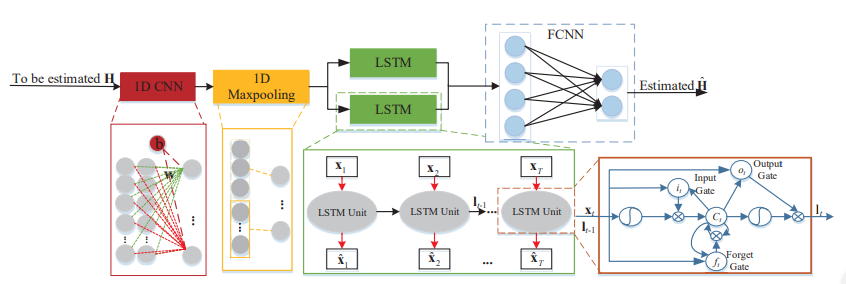

## Constructing the input data :

- We use SISO OFDM modulation for the input data with 4-QAM as the mapping technique.

- Cyclic prefix of length 16 is used to avoid ISI.

- Number of carriers is taken as $N_c$ = 64.

- We consider 20 symbols ($N_{s}$)  as one sub frame of the OFDM transmission. Each subframe has 4 pilots $N_p$ symbols evenly distributed.

nCarr = 64 ; % Number of carriers
cp_len = 16; % Length of cyclic prefix
nSym = 20;   % Number of symbols
Np = ceil(nSym/5); % Number of pilots
n_tx = 1 ;   % Number of transmitting antennaes
SNR = 20 ;   % Defning the SNR for the transmitted signals 

[ofdm_mod,ofdm_demod] = OFDMConfig(nCarr,cp_len,nSym,n_tx); % Creating the OFDM de/modulaion objects
[tx_sig, data_pil] = OFDM_Tx(ofdm_mod); % Creating the OFDM waveform which will be transmitted 
                                          % across the channel and getting the QAM data and pilots.
Xp = data_pil(:,1);

## Channel Modelling :

The channel array is already provided in the form of a .mat file which contains 16 taps evolving across time. 

For each 16 element channel array we convolve it with the OFDM symbol to get the channel distorted array.

We add AWGN noise to the this distorted array to get the final received array to which we apply deomulation and detection.

channel_train = load ('channel_train.mat'); % Training labels for neural network
channel_test = load ('channel_test.mat');  % Testing data for NN

## Preprocessing the input data for the neural network:

- The received OFDM signal is demdoulated and the pilots are extracted

- LS estimate is used to predict the $\hat{H}[k]$  values for those subcarriers where the pilots are present.

- The incomplete input $\hat{H}$matrix is fed into the neural network. The matrix is a $N_{c}$  x $N_{s}$. So wherever the pilots are present in the each of the symbols we have the $\hat{H_{LS}}[k]$ values and for the rest of the $N_{c} x (N_{s} - N_{p})
$ elements we consider them to be zeros, whose values will be determined by the neural network

h_subframe = channel_train.channel_train(1:nSym,:);
rx_sig = zeros(size(tx_sig));
for i= 1:nSym
    h= channel_train.channel_train(i,:); % Channel array for that symbol
    rx_sig(1+(i-1)*80:(i)*80) = channel_output(h,tx_sig(1+(i-1)*80:(i)*80),SNR); % Length of one symbol with CP is 80
end
Y = ofdm_demod(rx_sig); % One subframe of output

H_label = fft(h_subframe,nCarr,2); % Perform 64 point FFT along the rows of the channel array
H_actual = H_label';                  % Making it the right shape i.e. Nc x Ns (64x20)

H_input = LSE(Y,Xp,Np);             % Getting the input data 

## Constructing the layers of the neural network:

The following are the layers present in the neural network :

- Data is reshaped into a 3D structure of $N_s$x $N_c$ x $2$, where the 2 layers in the 3D is for real and complex parts of H.

- Concatenating the data into a 2D structure of $N_s$x $2*N_c$

- One dimensional CNN : $N_s$x $2*N_c$

- One dimensional Maxpooling : $N_s$x $2*N_c$

Note : Only required for time domain estimation, where every H is nothing but L values in time domain. So we will have 2*Nc*L values

- BiLSTM structure : $N_s$x $4*N_c$

- Fully Connected Neural Network : $N_s$x $2*N_c$

- Reshaping it back to $N_c$x $N_s$ x $2$

H_input_r_i = zeros([size(H_input),2]);
H_input_r_i(:,:,1) = real(H_input);
H_input_r_i(:,:,2) = imag(H_input);

layers = [depthConcatenationLayer(2,'Name','concat_1')
    convolution2dLayer([1,nCarr],nSym,'Name','CNN_1D')
    bilstmLayer(nSym,'Name','bi-lstm')
    fullyConnectedLayer(2*nCarr,'Name','FCNN')];